function [X_Est, P_Est, GT] = myEKF(out)
% myEKF Performs Extended Kalman Filtering for robot localization (X, Y, Yaw).
% VERSION MODIFIED to work with EKF_Localization class expecting Accel input.
%
% Inputs:
%   out: A structure containing sensor and ground truth data... (rest of help text unchanged)
%
% Outputs:
%   X_Est: Estimated state history [x; y; yaw] (3xN matrix)
%   P_Est: Estimated covariance history (3x3xN matrix)
%   GT: Ground truth state history [x; y; yaw] (3xN matrix)


fprintf('--- Starting myEKF Function (Modified for Accel Input) ---\n');


% --- 1. Load Calibration Parameters ---
calibration_file = 'sensor_calibration_parameters.mat';
if ~exist(calibration_file, 'file')
    error('Calibration file %s not found. Please run the calibration script first.', calibration_file);
end
load(calibration_file); % Loads 'calibrationParams' struct
fprintf('Loaded calibration parameters from: %s\n', calibration_file);


% --- 2. Configuration ---
% Define IMU axis indices
% *** CRITICAL: Verify these indices based on your IMU setup ***
gyro_yaw_axis_index = 1;     % Axis for Yaw rate (rotation around Z)
accel_fwd_axis_index = 2;    % Axis for Forward acceleration (e.g., robot's X or Y)
fprintf('INFO: Assuming Gyroscope Yaw Rate is axis index %d.\n', gyro_yaw_axis_index);
fprintf('INFO: Assuming Forward Accelerometer is axis index %d.\n', accel_fwd_axis_index);

% Define quaternion format and Euler convention (unchanged)
gt_quaternion_format = 'wxyz';
euler_convention = 'ZYX';
fprintf('INFO: Assuming GT quaternion format is [%s].\n', gt_quaternion_format);
fprintf('INFO: Using Euler angle convention ''%s'' for Yaw extraction.\n', euler_convention);


% --- 3. Extract Data & Time ---
try
    % Time vector (use ToF1 as reference)
    time_vec = out.Sensor_ToF1.time;
    N = length(time_vec);

    % --- Gyro Data ---
    if size(out.Sensor_GYRO.signals.values, 1) == 1 && size(out.Sensor_GYRO.signals.values, 2) == 3
        gyro_raw_data = squeeze(permute(out.Sensor_GYRO.signals.values, [2, 3, 1])); % 1x3xM -> 3xM
    elseif size(out.Sensor_GYRO.signals.values, 2) == 3
        gyro_raw_data = out.Sensor_GYRO.signals.values'; % Nx3 -> 3xN
    else
        error('Unexpected Gyro data format.');
    end
    gyro_time = out.Sensor_GYRO.time;

    % --- Accelerometer Data ---
    if isfield(out, 'Sensor_ACCEL') && ~isempty(out.Sensor_ACCEL.signals.values) % Check if Accel data exists
        if size(out.Sensor_ACCEL.signals.values, 1) == 1 && size(out.Sensor_ACCEL.signals.values, 2) == 3
            accel_raw_data = squeeze(permute(out.Sensor_ACCEL.signals.values, [2, 3, 1])); % 1x3xM -> 3xM
        elseif size(out.Sensor_ACCEL.signals.values, 2) == 3
            accel_raw_data = out.Sensor_ACCEL.signals.values'; % Nx3 -> 3xN
        else
            error('Unexpected Accelerometer data format.');
        end
        accel_time = out.Sensor_ACCEL.time;
        has_accel_data = true;
        fprintf('INFO: Accelerometer data found and extracted.\n');
    else
        warning('myEKF:NoAccelData', 'Accelerometer data (Sensor_ACCEL) not found in input structure. Prediction will not use acceleration.');
        has_accel_data = false;
        accel_raw_data = []; % Initialize empty
        accel_time = [];
    end

    % --- ToF Data ---
    tof1_data = out.Sensor_ToF1.signals.values;
    tof2_data = out.Sensor_ToF2.signals.values;
    tof3_data = out.Sensor_ToF3.signals.values;
    % tof_time = time_vec; % Assumed to share time_vec

    % --- Ground Truth Data ---
    gt_pos_data = out.GT_position.signals.values;
    gt_rot_data = out.GT_rotation.signals.values;
    gt_time = out.GT_position.time;

    fprintf('Data extracted successfully. Total time steps: %d\n', N);

catch ME
    error('Failed to extract data from input structure ''out'': %s\nPlease check field names and data dimensions.', ME.message);
end


% --- 4. Initial State and EKF Initialization ---
% Find initial Ground Truth state (unchanged)
t_start = time_vec(1);
[~, gt_start_idx] = min(abs(gt_time - t_start));
initial_pos_xy = gt_pos_data(gt_start_idx, 1:2)';
initial_quat = gt_rot_data(gt_start_idx, :);
if strcmp(lower(gt_quaternion_format), 'wxyz')
    initial_eul = quat2eul([initial_quat(1), initial_quat(2), initial_quat(3), initial_quat(4)], euler_convention);
elseif strcmp(lower(gt_quaternion_format), 'xyzw')
    initial_eul = quat2eul([initial_quat(4), initial_quat(1), initial_quat(2), initial_quat(3)], euler_convention);
else error('Unsupported gt_quaternion_format specified.'); end
initial_yaw = initial_eul(1);
initial_state = [initial_pos_xy; initial_yaw];

% Initial uncertainty (covariance P0) - unchanged
initial_cov = diag([0.05^2, 0.05^2, deg2rad(2)^2]);

% --- Set up EKF Parameters (BIASES AND PROCESS NOISES for the new predict method) ---
ekf_params = struct();
% Biases from calibration (or defaults if calibration file structure differs)
if isfield(calibrationParams, 'imu') && isfield(calibrationParams.imu, 'gyroBias')
    ekf_params.gyro_bias_z = calibrationParams.imu.gyroBias(gyro_yaw_axis_index);
else
    warning('Gyro bias not found in calibrationParams.imu.gyroBias. Using default 0.0015');
    ekf_params.gyro_bias_z = 0.0015;
end
if has_accel_data && isfield(calibrationParams, 'imu') && isfield(calibrationParams.imu, 'accelBias')
     ekf_params.accel_bias_fwd = calibrationParams.imu.accelBias(accel_fwd_axis_index);
else
     warning('Accel bias not found or Accel data missing. Using default 0.006');
     ekf_params.accel_bias_fwd = 0.006; % Use default if no data or not calibrated
end

% Process noise standard deviations (using values similar to myEKF example)
% Note: The original code used calibrated gyro variance directly. The new EKF
% class expects separate parameters. Adapt as needed.
ekf_params.process_noise_pos = 0.5;  % Tune this based on performance
ekf_params.process_noise_yaw_rate = sqrt(calibrationParams.imu.gyroVariance(gyro_yaw_axis_index)); % Use calibrated gyro noise std dev
ekf_params.process_noise_accel = 0.5; % Tune this based on performance

% Set initial velocity guess (can be tuned)
ekf_params.initial_velocity = 0.0; % Start assuming zero initial velocity

% Measurement noise standard deviation from calibration
measurement_noise_std = sqrt(calibrationParams.tof.variance);

% Create EKF instance with the new constructor signature
ekf = EKF_Localization(initial_state, initial_cov, ekf_params, measurement_noise_std); % Pass structure
fprintf('EKF initialized with initial state [%.3f, %.3f, %.3f deg].\n', ...
        initial_state(1), initial_state(2), rad2deg(initial_state(3)));


% --- 5. Prepare History Variables --- (unchanged)
X_Est = zeros(3, N);
P_Est = zeros(3, 3, N);
GT = zeros(3, N);
X_Est(:, 1) = ekf.x;
P_Est(:, :, 1) = ekf.P;
GT(:, 1) = initial_state;


% --- 6. Main EKF Loop ---
fprintf('Starting EKF processing loop...\n');
last_percent = -1;

for k = 1:(N-1) % Loop to predict state for step k+1
    % --- Calculate dt ---
    t_k = time_vec(k);
    t_kp1 = time_vec(k+1);
    dt = t_kp1 - t_k;

    if dt <= 0
        warning('myEKF:NonPositiveDt', 'Non-positive dt detected (%.4f) at step %d. Skipping prediction/update.', dt, k);
        X_Est(:, k+1) = X_Est(:, k); % Copy previous state
        P_Est(:, :, k+1) = P_Est(:, :, k); % Copy previous covariance
        % Get GT for this step
        [~, gt_idx] = min(abs(gt_time - t_kp1)); GT_pos = gt_pos_data(gt_idx, 1:2)'; GT_quat = gt_rot_data(gt_idx, :); if strcmp(lower(gt_quaternion_format), 'wxyz'); GT_eul = quat2eul([GT_quat(1), GT_quat(2), GT_quat(3), GT_quat(4)], euler_convention); else; GT_eul = quat2eul([GT_quat(4), GT_quat(1), GT_quat(2), GT_quat(3)], euler_convention); end; GT_yaw = GT_eul(1); GT(:, k+1) = [GT_pos; GT_yaw];
        continue; % Skip to next iteration
    end

    % --- Get Gyro Reading for Prediction Interval ---
    gyro_indices = find(gyro_time <= t_kp1);
    if isempty(gyro_indices)
        warning('myEKF:NoGyroData', 'No suitable gyro data found for interval ending at %.3f s (step %d). Assuming zero raw yaw rate.', t_kp1, k);
        gyro_z_raw = 0; % Assume zero RAW rate if no data
    else
        gyro_idx = gyro_indices(end);
        gyro_raw_vec = gyro_raw_data(:, gyro_idx);
        gyro_z_raw = gyro_raw_vec(gyro_yaw_axis_index); % Get RAW gyro reading
        % Bias correction is now done INSIDE ekf.predict
    end

    % --- Get Accelerometer Reading for Prediction Interval ---
    accel_fwd_raw = 0; % Default to zero raw acceleration
    if has_accel_data
        accel_indices = find(accel_time <= t_kp1);
        if isempty(accel_indices)
            % Keep accel_fwd_raw = 0;
            % warning('myEKF:NoAccelData', 'No suitable accel data found for interval ending at %.3f s (step %d). Assuming zero raw forward accel.', t_kp1, k);
            % This warning might be too frequent, consider removing if expected
        else
            accel_idx = accel_indices(end);
            accel_raw_vec = accel_raw_data(:, accel_idx);
            accel_fwd_raw = accel_raw_vec(accel_fwd_axis_index); % Get RAW forward accel
            % Bias correction is now done INSIDE ekf.predict
        end
    end % else, accel_fwd_raw remains 0 if no accel data overall


    % --- EKF Predict Step ---
    % CALLING WITH 3 ARGUMENTS NOW: raw gyro, raw accel, dt
    ekf.predict(gyro_z_raw, accel_fwd_raw, dt);


    % --- Get ToF Readings for Update Step --- (unchanged)
    current_tof_readings = [tof1_data(k+1); tof2_data(k+1); tof3_data(k+1)];
    valid_tof = isfinite(current_tof_readings) & current_tof_readings > 0;
    if all(valid_tof)
        ekf.update(current_tof_readings);
    else
         warning('myEKF:InvalidToF', 'Invalid ToF readings detected at step %d (time %.3f). Skipping EKF update.', k+1, t_kp1);
    end

    % --- Store Estimated State and Covariance --- (unchanged)
    X_Est(:, k+1) = ekf.x;
    P_Est(:, :, k+1) = ekf.P;

    % --- Get and Store Ground Truth for this time step --- (unchanged)
    [~, gt_idx] = min(abs(gt_time - t_kp1)); GT_pos = gt_pos_data(gt_idx, 1:2)'; GT_quat = gt_rot_data(gt_idx, :); if strcmp(lower(gt_quaternion_format), 'wxyz'); GT_eul = quat2eul([GT_quat(1), GT_quat(2), GT_quat(3), GT_quat(4)], euler_convention); else; GT_eul = quat2eul([GT_quat(4), GT_quat(1), GT_quat(2), GT_quat(3)], euler_convention); end; GT_yaw = GT_eul(1); GT(:, k+1) = [GT_pos; GT_yaw];

    % Display progress (unchanged)
    percent_done = floor(k / (N-1) * 100);
    if percent_done > last_percent && mod(percent_done, 10) == 0
        fprintf('  Processing... %d%%\n', percent_done);
        last_percent = percent_done;
    end

end % End of EKF loop

fprintf('EKF processing complete.\n');
fprintf('--- Exiting myEKF Function ---\n');

end % End of myEKF function

clear; clc; close all;

% --- 1. Load Data and Run EKF ---
data_file = 'trainingData/task1_4.mat'; % Or task2_2.mat, etc.
fprintf('Loading data from: %s\n', data_file);

Loading data from: trainingData/task1_4.mat


data = load(data_file);
data_struct_name = fieldnames(data);
if numel(data_struct_name) ~= 1
    error('Expected MAT file to contain a single structure variable.');
end
out = data.(data_struct_name{1}); % Use 'out' as the variable name matching the example

fprintf('\nRunning myEKF...\n');


Running myEKF...


[X_Est, P_Est, GT_ekf] = myEKF(out); % Run your EKF function

--- Starting myEKF Function (Modified for Accel Input) ---


Loaded calibration parameters from: sensor_calibration_parameters.mat
INFO: Assuming Gyroscope Yaw Rate is axis index 1.
INFO: Assuming Forward Accelerometer is axis index 2.
INFO: Assuming GT quaternion format is [wxyz].
INFO: Using Euler angle convention 'ZYX' for Yaw extraction.


Data extracted successfully. Total time steps: 2604


EKF Initialized (with myEKF Prediction Logic):
  Initial State (x): [0.033, -0.821, -1.624 rad]
  Initial Covariance (P):
    0.0025         0         0
         0    0.0025         0
         0         0    0.0012

  Gyro Bias Z: 0.0015, Accel Bias Fwd: 0.0060
  Process Noise Std Devs (Pos:0.50, YawRate:0.0011, Accel:0.50)
  Measurement Noise (R):
   1.0e-04 *

    0.0219         0         0
         0    0.3855         0
         0         0    0.0831

EKF initialized with initial state [0.033, -0.821, -93.033 deg].
Starting EKF processing loop...
DEBUG: ToF Yaw update DISABLED.
  Processing... 0%
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: To

% X_Est should be 3xN: [x; y; yaw]
% GT_ekf should be 3xN: [x; y; yaw] (ground truth processed by myEKF)
fprintf('myEKF finished.\n');

myEKF finished.



% --- 2. Prepare Data for compareTrajectories ---

% ------------------ Extract Ground Truth data from 'out' ------------------ %
% Use the raw GT data directly from 'out' for comparison consistency
pos_raw   = out.GT_position.signals.values;  % Usually Nx3 (X,Y,Z)
rot_raw   = out.GT_rotation.signals.values;  % Usually Nx4 (quaternion, check format!)
time_raw  = out.GT_position.time;            % Usually Nx1

% Define quaternion format used in GT_rotation.signals.values
% *** CRITICAL: Verify this matches your data format ***
gt_quaternion_format = 'wxyz'; % Options: 'wxyz' or 'xyzw'
fprintf('INFO: Assuming Raw GT quaternion format is [%s].\n', gt_quaternion_format);

INFO: Assuming Raw GT quaternion format is [wxyz].



% ------------------ Ensure Consistent Lengths ------------------ %
% Determine the number of estimates produced by EKF
N_est = size(X_Est, 2);

% Find corresponding indices in the raw time vector
% (Assuming EKF output corresponds directly to the input time vector length)
if N_est > length(time_raw)
    warning('EKF produced more estimates (%d) than raw time steps (%d). Truncating EKF output.', N_est, length(time_raw));
    N = length(time_raw);
    X_Est = X_Est(:, 1:N); % Truncate EKF results if necessary
else
    N = N_est; % Use the length of the EKF estimates
    % Truncate raw GT data to match EKF output length if needed
    if N > size(pos_raw, 1) || N > size(rot_raw, 1)
       error('Cannot compare: EKF output length (%d) exceeds raw GT data length.', N);
    end
    pos_raw = pos_raw(1:N, :);
    rot_raw = rot_raw(1:N, :);
    time_raw = time_raw(1:N);
end

fprintf('--- Comparing first N = %d time steps ---\n\n', N);

--- Comparing first N = 2604 time steps ---




% ------------------ Convert Ground Truth to rigidtform3d ------------------ %
gtTforms(N) = rigidtform3d;  % Preallocate
fprintf('Creating Ground Truth rigidtform3d array...\n');

Creating Ground Truth rigidtform3d array...


for i = 1:N
    % Extract quaternion based on assumed format
    if strcmpi(gt_quaternion_format, 'wxyz')
        qGT_raw = quaternion(rot_raw(i,1), rot_raw(i,2), rot_raw(i,3), rot_raw(i,4));
    elseif strcmpi(gt_quaternion_format, 'xyzw')
        qGT_raw = quaternion(rot_raw(i,4), rot_raw(i,1), rot_raw(i,2), rot_raw(i,3)); % w comes last
    else
        error('Invalid gt_quaternion_format specified.');
    end

    % Convert quaternion to rotation matrix (Requires Aerospace Toolbox)
    % Ensure you have this toolbox or use an alternative method if needed.
    try
        RGT = rotmat(qGT_raw, 'frame');
    catch ME
        if strcmp(ME.identifier, 'MATLAB:UndefinedFunction')
             error('Function ''rotmat'' not found. Is the Aerospace Toolbox installed and licensed?');
        else
            rethrow(ME);
        end
    end

    % Extract translation (use only X, Y, Z if available, assume Z=0 if only X,Y)
    if size(pos_raw, 2) >= 3
        tGT = pos_raw(i, 1:3); % Use X, Y, Z
    else
        tGT = [pos_raw(i, 1:2), 0]; % Use X, Y, assume Z=0
    end

    gtTforms(i) = rigidtform3d(RGT, tGT); % RGT should be 3x3, tGT should be 1x3
end
fprintf('Ground Truth rigidtform3d array created.\n');

Ground Truth rigidtform3d array created.



% ------------------ Convert EKF Estimated States to rigidtform3d ------------------ %
estTforms(N) = rigidtform3d;  % Preallocate
fprintf('Creating Estimated (EKF) rigidtform3d array...\n');

Creating Estimated (EKF) rigidtform3d array...


for i = 1:N
    % Estimated position (X, Y from EKF, assume Z=0)
    tEst = [X_Est(1, i), X_Est(2, i), 0]; % Create 1x3 row vector

    % Estimated orientation (Yaw from EKF)
    yaw_est = X_Est(3, i);
    cy = cos(yaw_est);
    sy = sin(yaw_est);

    % Create 3D rotation matrix from Yaw angle (rotation around Z-axis)
    REst = [ cy  -sy   0; ...
             sy   cy   0; ...
             0    0    1 ];

    % Create the rigid transform
    estTforms(i) = rigidtform3d(REst, tEst);
end
fprintf('Estimated (EKF) rigidtform3d array created.\n');

Estimated (EKF) rigidtform3d array created.




% --- 3. Compare Trajectories ---
fprintf('\n--- Comparing Trajectories using compareTrajectories ---\n');


--- Comparing Trajectories using compareTrajectories ---


Calling compareTrajectories with AlignmentType = 'rigid'...


compareTrajectories call successful.


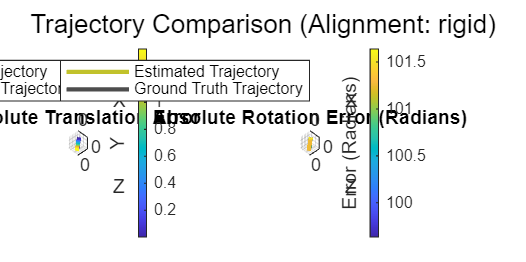

--- compareTrajectories executed and plotted successfully. ---



% Define the alignment type you want to use
% Options: 'none', 'rigid', 'affine', 'similarity'
alignment_type_to_use = 'rigid'; % Start with 'none', try 'rigid' later if needed

try
    % Requires Navigation Toolbox
    fprintf('Calling compareTrajectories with AlignmentType = ''%s''...\n', alignment_type_to_use);
    metrics = compareTrajectories(estTforms, gtTforms, 'AlignmentType', alignment_type_to_use);
    fprintf('compareTrajectories call successful.\n');

    % --- Plotting ---
    figure('Name', sprintf('compareTrajectories Results (Alignment: %s)', alignment_type_to_use));
    set(gcf, 'Position', [150, 150, 1000, 500]); % Adjust figure size/position

    subplot(1, 2, 1)
    try % Add try-catch for plotting in case metrics object is missing fields
        plot(metrics, "absolute-translation");
        title('Absolute Translation Error');
        grid on;
    catch plotME
        title('Absolute Translation Error (Plot Failed)');
        warning('Failed to plot absolute-translation: %s', plotME.message);
    end

    subplot(1, 2, 2)
     try % Add try-catch for plotting
        plot(metrics, "absolute-rotation");
        title('Absolute Rotation Error (Radians)'); % Update title for clarity
        ylabel('Error (Radians)'); % Add Y label
        grid on;
     catch plotME
        title('Absolute Rotation Error (Plot Failed)');
        warning('Failed to plot absolute-rotation: %s', plotME.message);
    end

    sgtitle(sprintf('Trajectory Comparison (Alignment: %s)', alignment_type_to_use));

    disp('--- compareTrajectories executed and plotted successfully. ---');

catch ME
    if contains(ME.identifier, 'UndefinedFunction') || contains(ME.identifier, 'LicenseCheckoutFailed')
        warning('Failed to run compareTrajectories: %s. Is the Navigation Toolbox installed and licensed?', ME.message);
    elseif contains(ME.message, 'Input poses contain NaN or Inf values')
         warning('Failed during trajectory comparison: Input poses contain NaN or Inf values. Check estTforms and gtTforms.');
         % Add code here to inspect estTforms/gtTforms if needed
         % find(isnan(estTforms))
    else
        warning('Failed during trajectory comparison or plotting: %s', ME.message);
        disp('Stack trace:');
        disp(ME.getReport);
    end
end


disp('--- End of comparison script ---');

--- End of comparison script ---



% Eval Script (Modified to Add Overlay Yaw Plot)


fprintf('Starting Evaluation Script...\n');

Starting Evaluation Script...




% ------------------ Extract Data ------------------ %
% Assumes 'out' and 'X_Est' are already loaded/generated
pos_GT_orig   = out.GT_position.signals.values;
rot_GT_quat_wxyz = out.GT_rotation.signals.values; % w,x,y,z format
timeVec  = out.GT_time.time;


if isrow(timeVec), timeVec = timeVec'; end
fprintf('Extracted GT Position, Rotation, and Time.\n');

Extracted GT Position, Rotation, and Time.




% --- Handle Potential Transpose Issues ---
if size(pos_GT_orig, 2) ~= 3 && size(pos_GT_orig, 1) == 3, pos_GT_orig = pos_GT_orig'; fprintf('Transposed original GT position data.\n'); end
if size(rot_GT_quat_wxyz, 2) ~= 4 && size(rot_GT_quat_wxyz, 1) == 4, rot_GT_quat_wxyz = rot_GT_quat_wxyz'; fprintf('Transposed original GT rotation data.\n'); end
% --- End Transpose Handling ---


% ------------------ Ensure Consistent Lengths ------------------ %
% --- MODIFIED EKF Output Check ---
% X_Est is now 3xN as generated by the class-based EKF.
if size(X_Est, 1) ~= 3 && size(X_Est, 2) == 3
    warning('X_Est seems to be Nx3, transposing to 3xN for consistency.');
    X_Est = X_Est';
elseif size(X_Est, 1) ~= 3
     error('X_Est should have 3 rows (x, y, yaw), but found %d rows.', size(X_Est, 1));
end
N_est = size(X_Est, 2); % Number of columns is N
% --- End Modified Check ---


N_gt_pos = size(pos_GT_orig, 1); N_gt_rot = size(rot_GT_quat_wxyz, 1);
N_time = length(timeVec);
N = min([N_gt_pos, N_gt_rot, N_time, N_est]);


if N < max([N_gt_pos, N_gt_rot, N_time, N_est])
    fprintf('--- Warning: Truncating data lengths from max(%d, %d, %d, %d) to shortest N = %d ---\n', N_gt_pos, N_gt_rot, N_time, N_est, N);
    pos_GT = pos_GT_orig(1:N, :); rot_GT_quat_wxyz = rot_GT_quat_wxyz(1:N, :);
    timeVec = timeVec(1:N); X_Est = X_Est(:, 1:N); % Use columns for EKF state
else
    fprintf('--- Data lengths consistent: N = %d ---\n', N);
    pos_GT = pos_GT_orig;
    % Ensure X_Est is also truncated if it was longer but N determined by GT/time
    if size(X_Est, 2) > N
        X_Est = X_Est(:, 1:N);
    end
end

--- Data lengths consistent: N = 2604 ---


if N == 0, error('Effective data length is zero after checking consistency.'); end


% ------------------ Convert Ground Truth Rotation to Yaw ------------------ %
fprintf('Converting Ground Truth rotation to Yaw (N=%d)...\n', N);

Converting Ground Truth rotation to Yaw (N=2604)...


yaw_GT = zeros(N, 1); valid_gt_quat = true(N, 1);
for i = 1:N
    try
        qGT = quaternion(rot_GT_quat_wxyz(i,1), rot_GT_quat_wxyz(i,2), rot_GT_quat_wxyz(i,3), rot_GT_quat_wxyz(i,4));
        qGT = normalize(qGT); eulGT = eulerd(qGT, 'ZYX', 'frame'); yaw_GT(i) = deg2rad(eulGT(1));
    catch ME_gt_conv, warning('Error converting GT quaternion at index %d: %s.', i, ME_gt_conv.message); yaw_GT(i) = NaN; valid_gt_quat(i) = false; end
end
yaw_GT = wrapToPi(yaw_GT);
fprintf('Ground Truth Yaw conversion complete.\n');

Ground Truth Yaw conversion complete.




% ------------------ Get Estimated Yaw ------------------ %
if size(X_Est, 1) < 3, error('X_Est does not contain Yaw data in the 3rd row.'); end
yaw_Est = wrapToPi(X_Est(3, :)'); % Get 3rd row, transpose to column, wrap
fprintf('Extracted Estimated Yaw.\n');

Extracted Estimated Yaw.




% ------------------ Convert Poses to rigidtform3d (Optional) --- %
% ... (code for rigidtform3d conversion remains the same) ...
fprintf('Converting poses to rigidtform3d arrays (N=%d)...\n', N);

Converting poses to rigidtform3d arrays (N=2604)...


gtTforms(N) = rigidtform3d; estTforms(N) = rigidtform3d;
valid_gt_pose = false(N,1); valid_est_pose = false(N,1); % Track valid poses
for i = 1:N
     % GT Pose
     if valid_gt_quat(i) && ~any(isnan(pos_GT(i,:)))
        try
            qGT = quaternion(rot_GT_quat_wxyz(i,1:4)); qGT = normalize(qGT); RGT = rotmat(qGT, 'frame'); tGT = pos_GT(i,1:min(3,end));
            if length(tGT) == 2, tGT = [tGT, 0]; end; gtTforms(i) = rigidtform3d(RGT, tGT(:)'); valid_gt_pose(i) = true;
        catch ME_gt_tform, warning('Error creating GT rigidtform3d at index %d: %s', i, ME_gt_tform.message); gtTforms(i) = rigidtform3d(); end
     else, gtTforms(i) = rigidtform3d(); end
     % Est Pose
    if ~any(isnan(X_Est(1:2, i))) && ~isnan(yaw_Est(i))
        try
            tEst = [X_Est(1, i), X_Est(2, i), 0]; yaw_est_i = yaw_Est(i);
            REst = [cos(yaw_est_i), -sin(yaw_est_i), 0; sin(yaw_est_i), cos(yaw_est_i), 0; 0, 0, 1];
            estTforms(i) = rigidtform3d(REst, tEst); valid_est_pose(i) = true;
        catch ME_est_tform, warning('Error creating Est rigidtform3d at index %d: %s', i, ME_est_tform.message); estTforms(i) = rigidtform3d(); end
    else, estTforms(i) = rigidtform3d(); end
end
fprintf('Pose conversions complete.\n');

Pose conversions complete.




% ------------------ Compare Trajectories & Calculate Key RMSEs --- %
fprintf('\n--- Trajectory Comparison Results ---\n');


--- Trajectory Comparison Results ---




% --- Run compareTrajectories if possible (Optional) ---
% ... (code for compareTrajectories remains the same) ...
metrics = []; canCompare = false;
try % Version/Toolbox check
    v = ver('MATLAB'); versionYear = str2double(regexp(v.Release, 'R(\d{4})[ab]', 'tokens', 'once'));
    if ~isempty(versionYear) && (versionYear >= 2024)
        reqToolbox = 'Navigation Toolbox'; allInstalledToolboxes = ver;
        if any(strcmp({allInstalledToolboxes.Name}, reqToolbox)), canCompare = true; fprintf('MATLAB version/toolbox OK for compareTrajectories.\n');
        else, fprintf('Required toolbox (%s) not found for compareTrajectories.\n', reqToolbox); end
    else, fprintf('MATLAB version might be too old for compareTrajectories.\n'); end
catch ME_ver, warning('Could not determine MATLAB version reliably: %s', ME_ver.message); end

MATLAB version/toolbox OK for compareTrajectories.




if ~canCompare, warning('compareTrajectories requires specific MATLAB version/toolbox. Skipping.');
else % Attempt to run compareTrajectories
    try
        validIdx = valid_est_pose & valid_gt_pose; % Use validity flags
        if sum(validIdx) < 2, warning('Not enough valid transforms (%d) to run compareTrajectories.', sum(validIdx));
        else
            metrics = compareTrajectories(estTforms(validIdx), gtTforms(validIdx), 'AlignmentType', 'rigid');
            fprintf('compareTrajectories executed (Specific metrics below are calculated manually).\n');
        end
    catch ME_compare, warning('Failed to execute compareTrajectories: %s', ME_compare.message); end
end

compareTrajectories executed (Specific metrics below are calculated manually).




% --- Calculate and Print Manual Position and Yaw Absolute RMSE --- %
% Position RMSE (Manual Calculation)
valid_pos_idx = ~isnan(X_Est(1, :))' & ~isnan(X_Est(2, :))' & ~isnan(pos_GT(:, 1)) & ~isnan(pos_GT(:, 2)); % Check EKF output columns
if sum(valid_pos_idx) > 0 && size(X_Est, 1) >= 2 && size(pos_GT, 2) >= 2 % Check EKF rows
    pos_err_x = X_Est(1, valid_pos_idx)' - pos_GT(valid_pos_idx, 1); % Transpose EKF part
    pos_err_y = X_Est(2, valid_pos_idx)' - pos_GT(valid_pos_idx, 2); % Transpose EKF part
    squared_pos_err = pos_err_x.^2 + pos_err_y.^2;
    rmse_position = sqrt(mean(squared_pos_err));
    fprintf('Position Absolute RMSE (Manual) (m):     %.4f\n', rmse_position);
else
    fprintf('Position Absolute RMSE (Manual) (m):     Cannot calculate.\n');
    rmse_position = NaN;
end

Position Absolute RMSE (Manual) (m):     1.2745




% Yaw RMSE (Manual Calculation)
valid_yaw_idx = ~isnan(yaw_Est) & ~isnan(yaw_GT);
if sum(valid_yaw_idx) > 0
    yaw_error = wrapToPi(yaw_Est(valid_yaw_idx) - yaw_GT(valid_yaw_idx));
    squared_yaw_err = yaw_error.^2;
    rmse_yaw_rad = sqrt(mean(squared_yaw_err));
    rmse_yaw_deg = rad2deg(rmse_yaw_rad);
    fprintf('Yaw Absolute RMSE (Manual) (degrees):    %.4f\n', rmse_yaw_deg);
else
    fprintf('Yaw Absolute RMSE (Manual) (degrees):    Cannot calculate.\n');
    rmse_yaw_deg = NaN;
end

Yaw Absolute RMSE (Manual) (degrees):    0.2342


fprintf('--- End Trajectory Comparison Results ---\n\n');

--- End Trajectory Comparison Results ---





% ------------------ Plot Position Comparison (Subplots) ------------------ %
% ... (Position plot code remains the same) ...
fprintf('Plotting Position: Ground Truth (Left) vs Estimate (Right)...\n');

Plotting Position: Ground Truth (Left) vs Estimate (Right)...


figure('Name', 'Position Comparison');
all_x = [pos_GT(:,1); X_Est(1,:)']; all_y = [pos_GT(:,2); X_Est(2,:)']; % Transpose EKF
x_lim = [min(all_x) max(all_x)]; y_lim = [min(all_y) max(all_y)];
x_range = diff(x_lim); y_range = diff(y_lim); margin = 0.05;
x_lim = x_lim + [-x_range*margin, x_range*margin]; y_lim = y_lim + [-y_range*margin, y_range*margin];
if x_range == 0, x_lim = x_lim + [-0.1, 0.1]; end; if y_range == 0, y_lim = y_lim + [-0.1, 0.1]; end
subplot(1, 2, 1); plot(pos_GT(:,1), pos_GT(:,2), 'b-', 'LineWidth', 1.5); title('Ground Truth Position'); xlabel('X Position (m)'); ylabel('Y Position (m)'); xlim(x_lim); ylim(y_lim); axis equal; grid on;
subplot(1, 2, 2); plot(X_Est(1,:), X_Est(2,:), 'r--', 'LineWidth', 1.5); title('EKF Estimated Position'); xlabel('X Position (m)'); ylabel('Y Position (m)'); xlim(x_lim); ylim(y_lim); axis equal; grid on;
try, sgtitle('Position Comparison: Ground Truth (Left) vs EKF Estimate (Right)'); catch, disp('sgtitle unavailable.'); end



% ------------------ Plot Yaw Comparison (Subplots) ------------------ %
% ... (Individual Yaw plot code remains the same) ...
fprintf('Plotting Yaw: Ground Truth (Left) vs Estimate (Right)...\n');

Plotting Yaw: Ground Truth (Left) vs Estimate (Right)...


figure('Name', 'Yaw Comparison');
if sum(valid_yaw_idx) > 0
    unwrapped_yaw_gt_deg = rad2deg(unwrap(yaw_GT(valid_yaw_idx))); unwrapped_yaw_est_deg = rad2deg(unwrap(yaw_Est(valid_yaw_idx)));
    all_yaw_deg = [unwrapped_yaw_gt_deg; unwrapped_yaw_est_deg]; y_lim_yaw = [min(all_yaw_deg) max(all_yaw_deg)];
    y_range_yaw = diff(y_lim_yaw); y_lim_yaw = y_lim_yaw + [-y_range_yaw*margin, y_range_yaw*margin];
    if y_range_yaw == 0, y_lim_yaw = y_lim_yaw + [-10, 10]; end
    subplot(1, 2, 1); plot(timeVec(valid_yaw_idx), unwrapped_yaw_gt_deg, 'b-', 'LineWidth', 1.5); title('Ground Truth Yaw'); xlabel('Time (s)'); ylabel('Unwrapped Yaw Angle (degrees)'); ylim(y_lim_yaw); grid on;
    subplot(1, 2, 2); plot(timeVec(valid_yaw_idx), unwrapped_yaw_est_deg, 'r--', 'LineWidth', 1.5); title('EKF Estimated Yaw'); xlabel('Time (s)'); ylabel('Unwrapped Yaw Angle (degrees)'); ylim(y_lim_yaw); grid on;
    try, sgtitle('Yaw Comparison: Ground Truth (Left) vs EKF Estimate (Right)'); catch, disp('sgtitle unavailable.'); end
else, subplot(1,1,1); title('Yaw Comparison (No valid data to plot)'); end



% ------------------ Plot Yaw Error ------------------ %
% ... (Yaw Error plot code remains the same) ...
fprintf('Plotting Yaw Estimation Error...\n');

Plotting Yaw Estimation Error...


figure('Name', 'Yaw Estimation Error');
if sum(valid_yaw_idx) > 0
    yaw_error_deg = rad2deg(wrapToPi(yaw_Est(valid_yaw_idx) - yaw_GT(valid_yaw_idx)));
    plot(timeVec(valid_yaw_idx), yaw_error_deg, 'k-', 'LineWidth', 1); xlabel('Time (s)'); ylabel('Yaw Error (degrees)'); title('Yaw Estimation Error (EKF - Ground Truth)'); grid on;
    max_err = max(abs(yaw_error_deg)); if ~isnan(max_err) && max_err > 0, ylim([-max(1, max_err*1.1), max(1, max_err*1.1)]); end
else, title('Yaw Estimation Error (No valid data to plot)'); end



% --- !!! NEW PLOT: OVERLAY GT vs ESTIMATED YAW !!! ---
fprintf('Plotting Yaw Overlay: Ground Truth vs Estimate...\n');

Plotting Yaw Overlay: Ground Truth vs Estimate...


figure('Name', 'Yaw Comparison: GT vs Estimate'); % Create a new figure
if sum(valid_yaw_idx) > 0
    % Use the unwrapped angles already calculated
    plot(timeVec(valid_yaw_idx), unwrapped_yaw_gt_deg, 'b-', 'LineWidth', 1.5);
    hold on; % Keep the plot for the next line
    plot(timeVec(valid_yaw_idx), unwrapped_yaw_est_deg, 'r--', 'LineWidth', 1.5);
    hold off; % Release the plot

    % Add labels and legend
    xlabel('Time (s)');
    ylabel('Unwrapped Yaw Angle (degrees)');
    title('Yaw Comparison: Ground Truth vs EKF Estimate');
    legend('Ground Truth Yaw', 'EKF Estimated Yaw', 'Location', 'best');
    grid on;
    % Use the same y-limits as the individual yaw plots for consistency
    ylim(y_lim_yaw);
else
    title('Yaw Comparison: GT vs Estimate (No valid data to plot)');
end

% --- !!! END NEW PLOT !!! ---


fprintf('--- End of Evaluation Script ---\n');

--- End of Evaluation Script ---
